# Network Intrusion Detector

clear;
clc;

a) load dataset

dataset2 = load("cw_dataset_2class.txt");

% % columns 1-41 preprocess data
% features = dataset2(:,1:41);
% 
% % columns 42 is for traffic type
% trafficType = dataset2(:,42);

% dataset2 = normalize(dataset2)

% shuffle data
selectRows = size(dataset2,1);
shuffle = randperm(selectRows);
shuffledDataset = dataset2(shuffle, :);



% dataset2 = dataset2';

shuffledDataset = shuffledDataset';
% [trainingDataset, validationDataset, testingDataset] = dividerand(dataset2, 2/3, 0, 1/3);
[trainingDataset, validationDataset, testingDataset] = dividerand(shuffledDataset, 2/3, 0, 1/3);
% trainingDataset = trainingDataset';
% validationDataset = validationDataset';
% testingDataset = testingDataset';

b) Create training data, training target, testing data and testing target.

trainingData = trainingDataset(1:41,:);
trainingTargetData = trainingDataset(42,:);

testingData = testingDataset(1:41,:);
testingTarget = testingDataset(42,:);
% trainingData = trainingDataset(:,1:41)
% trainingTargetData = trainingDataset(:,42)
% 
% testingData = testingDataset(:,1:41);
% testingTarget = testingDataset(:,42);

c) Select Pattern Recognition Neural Network (patternnet)

% Define the number of neurons
numOfNeurons = 10;

%select pattern net
net = patternnet(numOfNeurons);

d) Define the number of neurons of the neural network (assume only one hidden layer), define the neural network parameters, e.g. epochs, error goal, and learning rate.

% Define epoch, error goal and learning rate
epochs = 50;
errorGoal = 0.001;
learningRate = 0.1;

% Not sure if these are correct parameter names

net.trainParam.epochs = epochs;
net.trainParam.goal = errorGoal;
net.trainParam.lr = learningRate;

e) Train the neural network based on the training dataset created, and view the trained net (similar as Figure 5, input and output numbers are just for illustration).

[net, tr] = train(net, trainingData, trainingTargetData);
view(net)

predictedData = net(testingData);
perp = perform(net, testingTarget, predictedData);
disp(perp);

    0.0188



tr

tr = struct with fields:
        trainFcn: 'trainscg'
      trainParam: [1×1 struct]
      performFcn: 'crossentropy'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [4 5 7 8 10 11 13 14 15 16 18 19 21 23 24 25 26 28 29 30 32 35 36 38 40 41 42 44 45 46 47 48 50 51 52 56 58 59 60 62 63 64 65 66 67 68 72 74 75 77 78 79 80 84 87 89 90 92 94 97 98 100 104 105 106 107 108 109 112 113 115 116 117 119 … ]
          valInd: [1 2 9 12 22 27 31 33 34 39 53 57 61 69 70 71 82 83 86 91 93 95 96 99 101 102 111 118 120 121 122 153 162 164 171 172 183 188 193 197 207 212 213 217 228 229 233 256 258 262 267 270 282 286 288 297 307 331 332 342 345 360 364 375 … ]
         testInd: [3 6 17 20 37 43 49 54 55 73 76 81 85 88 103 110 114 126 128 134 135 141 145 163 166 180 181 198 214 220 222 231 239 242 245 250 254 261 265 272 293 295 314 325 329 336 337 341 344 347 353 363 366 371 383 

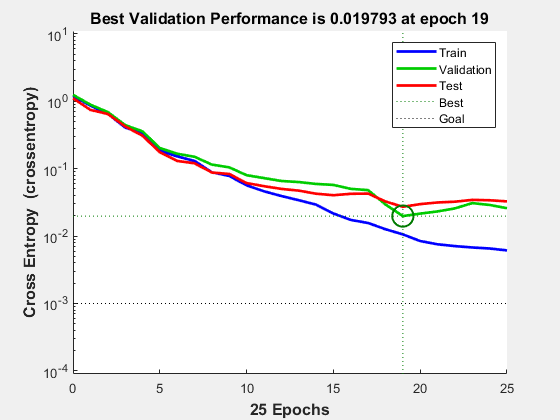

plotperform(tr);%plot performance graph

f) Test the trained net using testing dataset and evaluate its performance (e.g. classifier accuracy and recall rate). You may run several times for training and testing to get an average performance value. Why does each run has different results?

g) Explore how neural network parameters (e.g. learning rate) and the number of neurons affect the performance of classifier. Explain what are normal stopping criteria for training.

h) After completion of intrusion detector for just two classes (‘normal’ and ‘attack’), you now decide to further develop intrusion detection classifier for 3 classes (i.e. ‘normal’, DoS and probing attack), and 5 classes (i.e. ‘normal’, ‘smurf’, ‘neptune, ‘satan’ and ‘ipsweep’). What performance can you get for the intrusion detection classifier?

% dataset5 = fscanf("cw_dataset.txt")


% clear;
% fid = fopen('cw_dataset.txt','r');
% data = textscan(fid, '%s', 'Delimiter', '\n'); %read all data as string
% data = data{1};
% for i = 1:size(data,1)
%     nData{i,:} = strsplit(data{i},' '); %split data whitespace
%     if (mod(i,2)==1) %checks if uneven/POINT or even/PATH
%         nnData{i,1} = str2num(cell2mat(nData{i}(2))); %get POINT 1st number
%         nnData{i,2} = str2num(cell2mat(nData{i}(3))); %get POINT 2nd number
%     else
%         nnData{i,3} = str2num(cell2mat(nData{i}(2))); %get PATH 1st number
%     end
% end
% nnData = cell2mat(nnData); %make double matrix / removes empty rows
% fclose(fid);